clc;clear all;

R = 0.92/2; %radius
rpm = 1000;
Vinf = 0; 
z_R = 0.5:0.5:3;
z = z_R*R;
T = 2.4; %thrust from openVSP
rho = 1.225;
A = pi*R^2;
omega = rpm*2*pi/60;

Vi = sqrt(T./(2.*rho.*A)); %inflow inudced velocity
V_tip = omega.*R;

nue = Vinf./V_tip; %advance ratio

lamda_i = Vi./V_tip; %inflow induced ratio

a = (R./(4.*z)).^2;
b = (nue+lamda_i).^2;

Tige_Toge = 1./(1-(a./(1+b))); %Thrust ratio
% Tige_Toge = 1/(1-a)
Tige = Tige_Toge.*T; % Thrust -in gorund effect

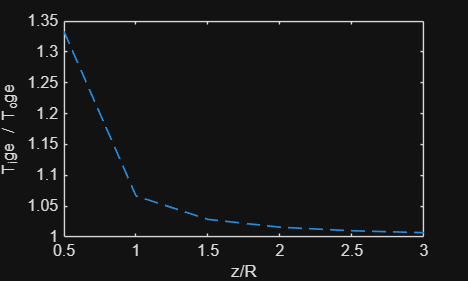

plot(z_R,Tige_Toge,"LineWidth",1,"LineStyle","--");
xlabel("z/R");
ylabel("T_ige / T_oge");